# **Dual regression**

Dual regression is an multivariate data analysis technique used in neuroimaging, particularly with functional magnetic resonance imaging (fMRI), to explore and examine brain networks. It's often applied in the context of resting-state fMRI studies to investigate how brain regions associate with networks over time. However, it can be applied to any image series.  In the example below, the fMRI image series is a sample of contrast images, stored in the variable target_obj.

In addition, the networks can be generalized to any set of seed maps, which we store in the variable seed_maps.

Dual regression is valuable for comparing brain networks (or, more generally, seed-related time series and maps) vary across subjects or conditions, and for studying how networks are altered in various populations, e.g.,psychiatric or neurological disorders, or correlate with individual differences.

Analyses can be done on both the seed map-related time series (or, more generally, image series), which comes from the spatial regression, and on the voxel-wise maps of associations between voxels and seeds, which comes from the temporal regression.  

## Dual Regression Process

The dual regression procedure generally involves two main stages, which are applied after obtaining the seed maps.  Traditionally, the seed maps come from an initial independent component analysis (ICA)  on the entire dataset (e.g., across all subjects) to extract a set of group-level independent components (ICs), which represent common spatial patterns or brain networks across the group.  

Here, we load pre-calculated seed maps from Neurosynth. These are factors calculated across different topic maps, each a pattern of brain activity associated with a profile of functional tasks.  The topic maps are nearly uncorrelated, which is helpful.

1. Spatial Regression (First Stage)

   - Seed maps are used as spatial templates.

   - For each subject, a spatial regression is performed using the group ICs as spatial maps. This regression estimates the time courses that best match the spatial patterns of each IC within each subject's data.

   - The result is a set of time courses for each IC, unique to each subject, capturing how each brain network fluctuates over time.

2. **Temporal Regression (Second Stage)**:

   - The estimated time courses from the first stage are then used in a second regression, but now targeting the original fMRI data.

   - In this stage, temporal regression is applied using each IC’s time course to derive subject-specific spatial maps that correspond to each group-level IC.

   - The outcome is a set of spatial maps that reflect how each brain network (identified by ICA) is represented uniquely in each subject.

### Variables in the example script

**Target data**

target_obj is a series of images, often a time series, with v voxels x n images.

target_obj can be partitioned into:

- images in different task conditions or states (e.g., positive vs. negative movies)

- images belonging to different participants (i.e., participants are stacked)

- images belonging to different groups of participants (G; e.g., patients vs. controls)

- images belonging to individuals with different continuous characteristics (e.g., emotion regulation success)

**Seed images**

- These are spatial maps with some semantic meaning -- e.g., functional networks, topics from neurosynth, ICA components. We use k for k maps, one per seed. They are stored in seed_maps.

- The seed maps can also be thought of as an embedding space for the target images. Each target image is mapped as a vector in seed (embedding) space. The dimensions of the space are defined by the seeds. Target images are projected onto the subspace spanned by the seeds. 

- The stability and interpretability of the loadings depends on whether the seed images are relatively uncorrelated.

- The interpretability additionally depends on the meaning of the seed maps, i.e., how they map to topics, systems, or networks.

**Loadings **

- These are produced by the spatial regression. They consist of a image series (across n images) for each spatial seed map. 

- If target_obj is a time series, loadings are the time courses for each seed. If seeds are networks, loadings are the time series of activity in each network.

- If the image series is partitioned into task conditions or groups, or is associated with individual differences, you can use t-tests or regression to compare image values for a given seed across groups , and to identify which seed maps are differentially expressed across groups or individuals.

**Individualized spatial maps**

- These are produced by the temporal regression. These will be most stable when the image series is long and there are many data points for the temporal regression.

- These are the maps of how the data images in target_obj load onto each seed, and are stored in individualized_maps.  For k seeds, there are k spatial maps.

- These can be reconstructed for different individuals and/or different groups of individuals, which will yield one set of spatial maps for each individual or group.

- If you reconstruct spatial maps for each of a series of individuals, you can then collect the spatial maps across individuals for a given seed (or for each seed), and use T-tests to compare groups, or use regression to relate individual differences in the spatial loadings for the seed with other external variables.


obj = load('neurosynth_topics_v4_FI_21_factors.mat');
seed_maps = obj.factor_maps;
cond(seed_maps.dat)

ans = 1.9734

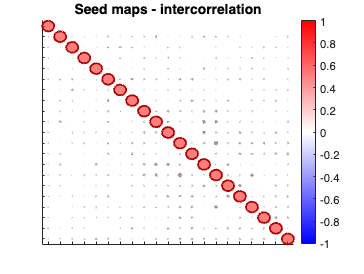

plot_correlation_matrix(seed_maps.dat);
title('Seed maps - intercorrelation')

target_obj = load_image_set('emotionreg');  % time series or other image series


## Preprocess maps

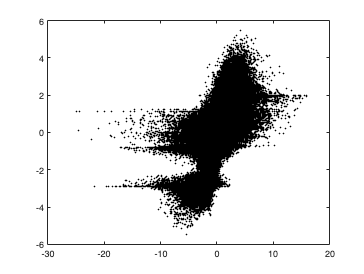

ans = single
0.6136

% Resample so seed and target spaces match
% Choices: normalize maps to standardize loadings
normalize_images = false;

seed_maps = resample_space(seed_maps, target_obj);

if normalize_images

    seed_maps = rescale(seed_maps, 'zscoreimages');
    target_obj = rescale(target_obj, 'zscoreimages');

end


## Spatial regression

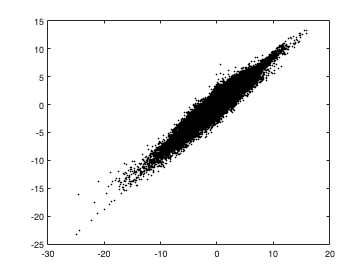

ans = single
0.9397

% Y = Xb + e
% Y is target obj spatial maps (separately, but can combine in matrix form)
% X is seed maps

intcpt = ones(size(seed_maps.dat, 1), 1);
X = [seed_maps.dat intcpt];

b = pinv(X) * target_obj.dat;  % [# seed maps + 1 x # target maps]

% How well can we reconstruct the original images?
% in-sample fits
fits = X * b;
figure; plot(target_obj.dat(:), fits(:), 'k.');
corr(target_obj.dat(:), fits(:))

% We can make inferences using b' by correlating them with other variables.
% b' is time/image series x seeds. 
% call this loadings
% If target_obj is a time series, loadings are the time courses for each
% seed.
loadings = b(1:end - 1, :)';

## Temporal regression

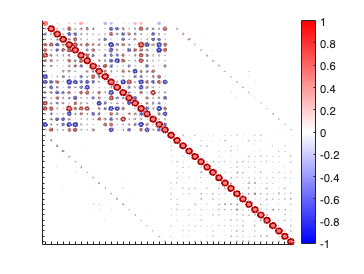

ans = struct with fields:
         p_thr: 0.0500
          sigu: [42×42 logical]
             r: [42×42 double]
             p: [42×42 double]
           sig: [42×42 logical]
    dospearman: 0
     dopartial: 0
     var_names: {}


% Y = Xb + e

% Y is time/image series in each voxel (separately, but can combine in matrix form)
% X is loadings, images x seeds

intcpt_t = ones(size(loadings, 1), 1);
X_t = [loadings intcpt_t];

Y = target_obj.dat';
b_t = pinv(X_t) * Y;  % [# seed maps + 1 x # target maps]

% How well can we reconstruct the original images?
% in-sample fits
fits = X_t * b_t;
figure; plot(Y(:), fits(:), 'k.');
corr(Y(:), fits(:))

% individualized_maps are the loadings of voxels onto seeds
% if a seed a "network", they reflect the loadings of voxels onto networks
individualized_maps = seed_maps;
individualized_maps.dat = b_t(1:end - 1, :)';

plot_correlation_matrix([individualized_maps.dat seed_maps.dat])
